10)

a) Determina la transformada de Fourier discreta de la imagen de la figura 42(a).  

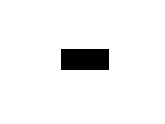

% Crear una imagen de 150x150 con fondo blanco (valor 1)
I=ones(150,150); 
% Dibujar un rectángulo negro (valor 0)
I(60:90,40:110)=0;
imshow(I,'initialMagnification','fit')

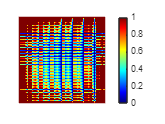


F = fft2(I);
F1 = log(1 + abs(F));
figure,...
imshow(F1,'initialMagnification','fit')
colormap(jet); colorbar

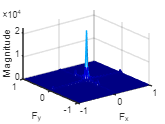

freqz2(F1) 

b) Determina la transformada de Fourier discreta de la imagen de la figura 42(a) pero con el valor  |F(0,0)|  en el centro de la representación.  

I = ones(150,150);
I(60:90,40:110)=0;
imshow(I,'initialMagnification','fit')

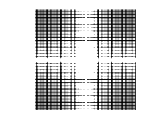


F = fft2(I);
F1 = fftshift(F);
F2 = log(1 + abs(F1));
figure,...
imshow(F2,'initialMagnification','fit');

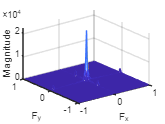

freqz2(F2) 

c) Determina la transformada de Fourier discreta de la imagen de la figura 44(a).  

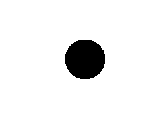

I = ones(150,150);
for i = 1:150
    for j = 1:150
        if (i-75)^2 + (j-75)^2 < 900
            I(i,j) = 0;
        end
    end
end
imshow(I,'initialMagnification','fit')

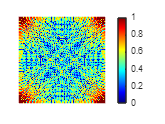


F = fft2(I);
F1 = log(1 + abs(F));
figure,imshow(F1/4,'initialMagnification','fit')
colormap(jet); colorbar

d) Determina la transformada de Fourier discreta de la imagen de la figura 45(a) pero con el valor de  |F(0,0)|  en el centro de la imagen. 

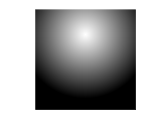

% Coordenadas del foco (cambiar posición y valores)

a = 100;  
b = 200;  
% Dimensiones de la imagen (MxN)
M = 400; 
N = 400; 
% Construcción de la imagen
for x = 1:M
    for y = 1:N
        I(x, y) = (255 - sqrt((x - a)^2 + (y - b)^2)) / 255;
    end
end
imshow(I,'initialMagnification','fit')

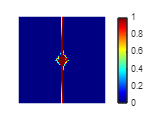


F = fft2(I);
F3 = fftshift(F);
figure,...
imshow(1 + log(abs(F3)),'initialMagnification','fit')
colormap(jet); colorbar

e) Determina la transformada de Fourier discreta de la imagen de la figura 46(a) pero con el valor de  |F(0,0)| en el centro de la imagen. 

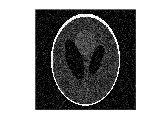

I = phantom(256);  % Imagen tipo tomografía
I = imnoise(I, 'gaussian', 0, 0.01);  % Añadimos ruido para hacerla distinta
imshow(I,'initialMagnification','fit')

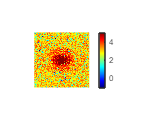


F = fft2(I);
F1 = fftshift(F);
figure,...
imshow(log(abs(F1)), [-1 5])
colormap(jet); colorbar

a) ¿Qué hace fft2? ¿Para que se genera la variable F1? ¿Hay diferencia si el rectángulo es vertical?

- `fft2`: Calcula la Transformada de Fourier bidimensional, transforma la imagen del dominio espacial al dominio de frecuencia.

- `F1`: Almacena la magnitud de la transformada de Fourier de la imagen.

- **¿Diferencia si el rectángulo es vertical?**: Sí, la orientación del rectángulo afecta. Si el rectángulo es vertical, las componentes de alta frecuencia aparecerán a lo largo del eje horizontal, y viceversa si el rectángulo es horizontal.

b) ¿Qué cambio hay entre la Figura 42 y 43 del guion? ¿Qué hace fftshift? ¿Y si en lugar de usar 1 se usa 10, 100, 0.1 o 0.001?

- **Cambio entre Figura 42 y 43**: La diferencia es que en la **Figura 42**, muestra las frecuencias de baja a alta de manera lineal, mientras que en la **Figura 43** se utiliza `fftshift `lo que facilita su interpretación.

- `fftshift`: Desplaza las bajas frecuencias al centro de la imagen para facilitar la visualización de las frecuencias altas en las esquinas.

- **¿Y si en lugar de usar 1 se usa 10, 100, 0.1 o 0.001?**: Usar un valor mayor como 10 o 100 amplifica la intensidad de las frecuencias altas, haciendo el espectro más brillante. Usar valores pequeños como 0.1 o 0.001 atenúa las frecuencias, oscureciendo el espectro y perdiendo detalle en los componentes de alta frecuencia.